Lewostronne mnożenie przez macierz, można interpretować jako liniowe przekształcenie przestrzeni. Każda kolumna macierzy wyraża przekształcenie składowych w poszczególnych wymiarach. Zasada ta zilustrowana będzie na poniższych rysunkach.

clear all;
close all;

dfVal=false

dfVal = logical
   0


flagg='UserDefined'

flagg = 'UserDefined'

podpisy=true

podpisy = logical
   1



 

if dfVal==true
    x0=3;
    y0=2;  
else    
    x0=input('Podaj składową x przekształcanego wektora:')
    y0=input('Podaj składową y przekształcanego wektora:')
end

x0 = -1

y0 = 5


v0=[x0;y0]

v0 =     -1
     5


if flagg=="skala_plus"
    transM=[2,0; 0,2];
elseif flagg=="skala_minus"
    transM=[-3,0; 0,-3];
elseif flagg=="obrot90st"
    transM=[0,-1; 1,0];
elseif flagg=="pochyl"
    transM=[3,0; 0,1];
elseif flagg=="UserDefined"    
    transM=input('Podaj macierz przekształcenia (2x2):')
    if size(transM)~=[2 2]
        display('Uruchom programjeszcze raz i podaj macierz 2x2!')
        return
    end
else
    display('Nie wybrano żadnego przekształcenia. Uruchom skrypt jeszcze raz.')
    return
end

transM =      3    -1
     2     2




A=-5;
B=5;
N=B-A+1;
v = linspace(A,B,N);
lines(1,:) = repelem(v,N);
lines(2,:) = repmat(v,1,N);

%rysunek przed transpozycją
figure()
hold on
for i=1:N
    plot(lines(1,(i-1)*N+1:i*N),lines(2,(i-1)*N+1:i*N),'k:')
    temp=i+linspace(1,N^2-N+1,N)-1;
    plot(lines(1,temp),lines(2,temp),'k:')
end
plot([0 v0(1)], [0 v0(2)], '-g','LineWidth',2)
plot([0 1], [0 0], '-y','LineWidth',2)
plot([0 0], [0 1], '-c','LineWidth',2.2)
if podpisy==true
    str="V=["+v0(1)+","+v0(2)+"]"
    t=text(v0(1),v0(2),str);
    t.FontSize=15;
    if v0(1)<=0
       t.HorizontalAlignment="right"; 
    end
    t=text(1,0,'i');
    t.FontSize=15;
    t=text(0,1,'j');
    t.FontSize=15;
    t.HorizontalAlignment="right"; 
end

str = "V=[-1,5]"

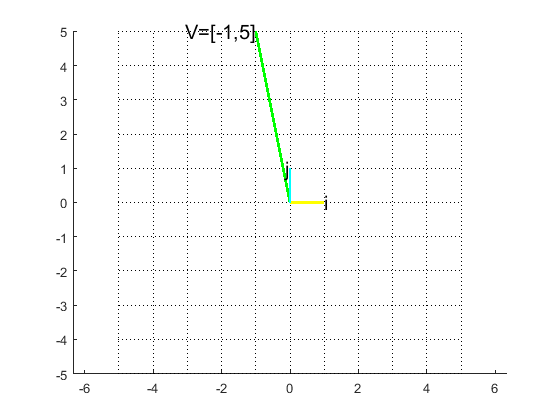

axis equal
hold off



%%%%%%%%%%%%%%%
%Transformacja:
for i=1:length(lines(1,:))
    linesk(:,i)=transM*lines(:,i);
end
vk=transM*v0

vk =     -8
     8



%rysunek po transpozycji
figure()
hold on
for i=1:N
    plot(linesk(1,(i-1)*N+1:i*N),linesk(2,(i-1)*N+1:i*N),'r:','LineWidth',1.2)
    temp=i+linspace(1,N^2-N+1,N)-1;
    plot(linesk(1,temp),linesk(2,temp),'r:','LineWidth',1.2)
end
plot([0 vk(1)], [0 vk(2)], 'color','#77AC30','LineWidth',2)
plot([0 transM(1,1)], [0 transM(2,1)], 'color','#EDB120','LineWidth',2)
plot([0 transM(1,2)], [0 transM(2,2)], 'color','#4DBEEE','LineWidth',2.2)
if podpisy==true
    str="Vk=["+vk(1)+","+vk(2)+"]";
    t=text(vk(1),vk(2),str);
    t.FontSize=15;
    if vk(1)<=0
       t.HorizontalAlignment="right"; 
    end
    t=text(transM(1,1),transM(2,1),'iprim');
    if transM(1,1)<=0
       t.HorizontalAlignment="right"; 
    end
    t=text(transM(1,2),transM(2,2),'jprim');
    if transM(1,2)<=0
       t.HorizontalAlignment="right"; 
    end
end
    
for i=1:N
    plot(lines(1,(i-1)*N+1:i*N),lines(2,(i-1)*N+1:i*N),'k:','LineWidth',1.2)
    temp=i+linspace(1,N^2-N+1,N)-1;
    plot(lines(1,temp),lines(2,temp),'k:','LineWidth',1.2)
end
p1=plot([0 v0(1)], [0 v0(2)], '-g','LineWidth',2);
%alpha(p1,0.5)
plot([0 1], [0 0], '-y','LineWidth',2)
plot([0 0], [0 1], '-c','LineWidth',2.2)
if podpisy==true
    str="V0=["+v0(1)+","+v0(2)+"]"
    t=text(v0(1),v0(2),str);
    t.FontSize=15;
    if v0(1)<=0
       t.HorizontalAlignment="right"; 
    end
    t=text(1,0,'i');
    t=text(0,1,'j');
    t.HorizontalAlignment="right"; 
end

str = "V0=[-1,5]"

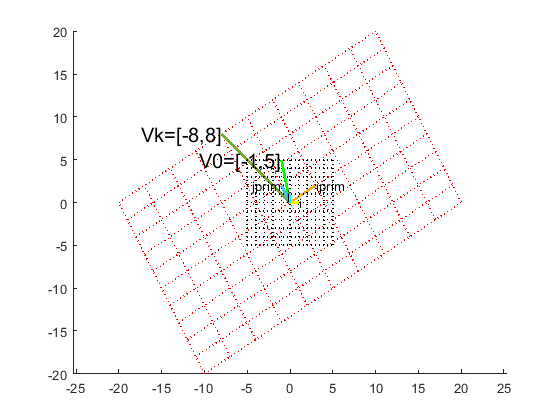

axis equal
hold off

Zwróć uwagę, że:

- Rysunki można powiększać, resetować powiększenie, przesuwać, otworzyć w odzdzielnym oknie, wyeksportować itp. - za pomocą ikonek, które pojawiają się po najechaniu kursorem w prawy górny obszar figury.

- Czynnik pierwszy rozwinięcia w szereg Taylora jest składową stałą, czynnik drugi jest funkcją liniową, czynnik trzeci jest wielomianem drugiego stopnia itd. - inaczej mówiąc szereg Taylora, to suma wielomianów.

- Po uwzględnieniu wystarczającej liczby (skończonej) czynników każdy wielomian zostanie odtworzony w sposób dokładny.

- Błędy wyświetlane przez maszynę w takim przypadku są efektem zjawisk numerycznych (np. transmisji błędów reprezentacji itp), o których będziemy mówić w trakcie WNUM.

- Funkcje niewielomianowe nie dają się odtworzyć dokładnie za pomocą skończonej liczby czynników szeregu Taylora.

- Przybliżenie funkcji jest zawsze bardzo dobre w bezpośredniej bliskości punktu rozwinięcia.

- Generalnie rysują się różne piękne kształty!